decompData = readtable('decompdata.xlsx')

decompData = 7×4 table
    Time      HI        H2        I2  
    ____    ______    ______    ______

      0       0.02         0         0
     50     0.0176    0.0011    0.0014
    100     0.0157    0.0035    0.0021
    150     0.0139    0.0054    0.0043
    200     0.0114    0.0073    0.0069
    250       0.01    0.0094    0.0089
    300     0.0091    0.0105    0.0095



figure()
f = plot(decompData.Time, [decompData.HI, decompData.H2, decompData.I2],'Marker','*')

f =   3×1 Line array:

  Line
  Line
  Line


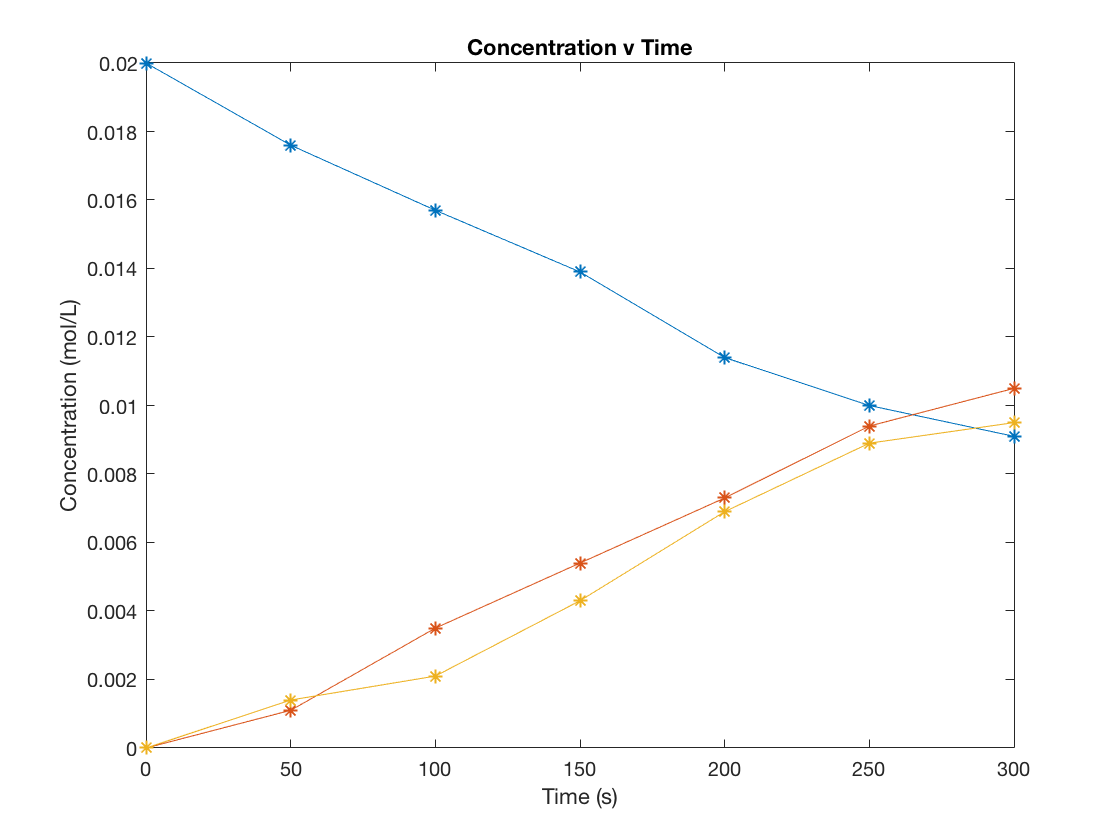

xlabel('Time (s)');
ylabel('Concentration (mol/L)');
title('Concentration v Time');


figure ()
f = plot(decompData.Time, decompData.HI, 'Marker', '*')

f =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '*'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 50 100 150 200 250 300]
              YData: [0.0200 0.0176 0.0157 0.0139 0.0114 0.0100 0.0091]
              ZData: [1×0 double]

  Show all properties


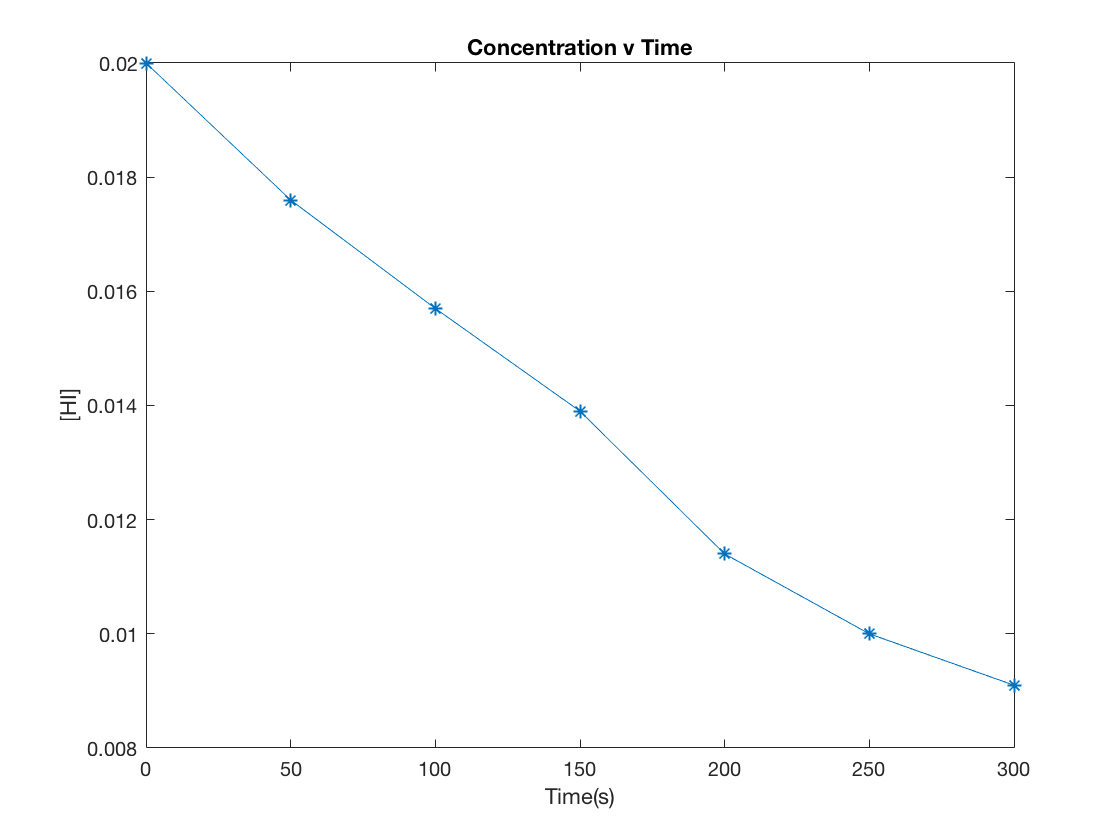


xlabel('Time(s)');
ylabel('[HI]')
title('Concentration v Time')


figure ()
x1 = decompData.Time

x1 =      0
    50
   100
   150
   200
   250
   300


y1 = log(decompData.HI)

y1 =    -3.9120
   -4.0399
   -4.1541
   -4.2759
   -4.4741
   -4.6052
   -4.6995


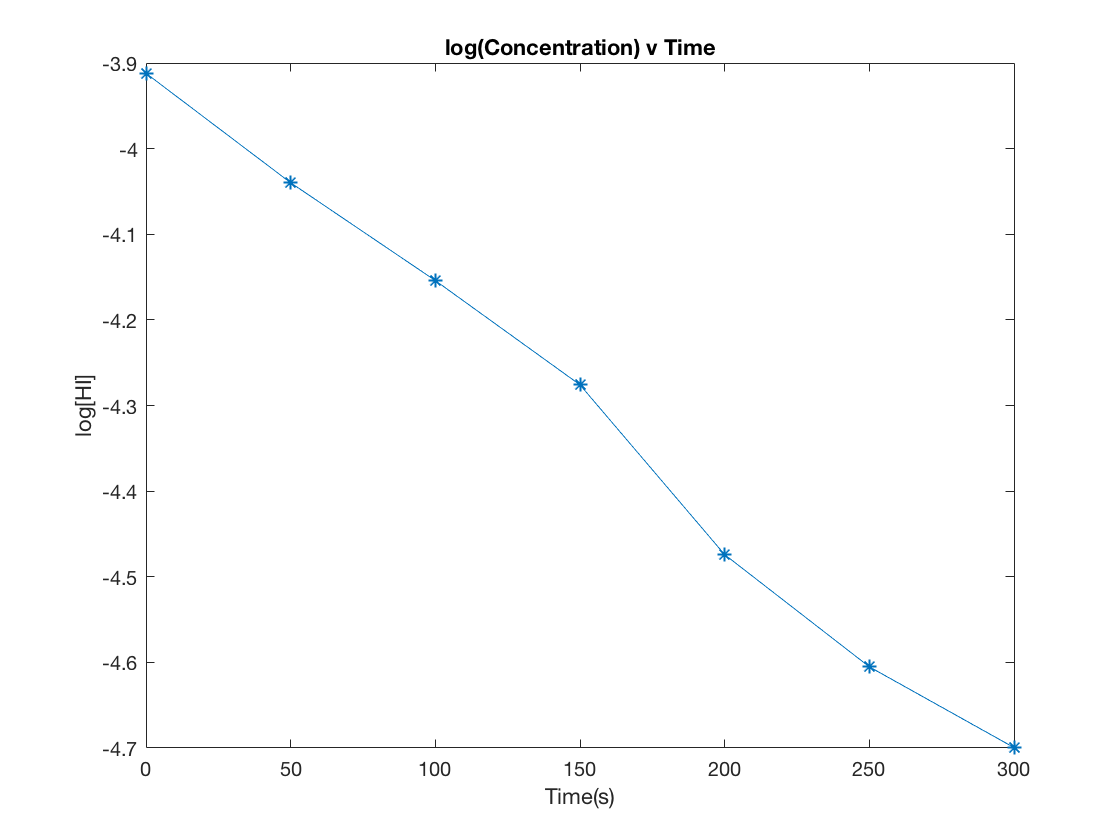

plot(x1,y1,'Marker', '*') 
xlabel('Time(s)');
ylabel('log[HI]')
title('log(Concentration) v Time')


figure ()
x2 = decompData.Time

x2 =      0
    50
   100
   150
   200
   250
   300


y2 = [50 56.81 63.69 71.94 87.72 100 109.89]

y2 =    50.0000   56.8100   63.6900   71.9400   87.7200  100.0000  109.8900


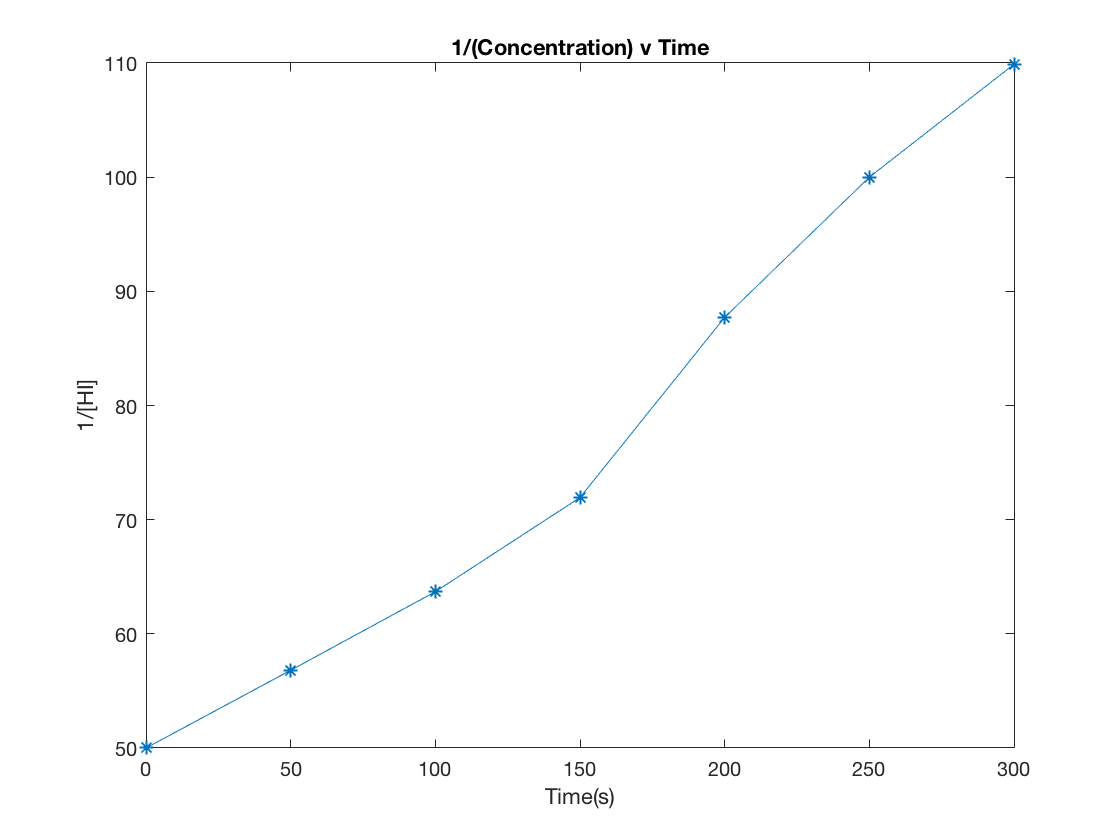

plot(x2,(y2),'Marker', '*');
xlabel('Time(s)');
ylabel('1/[HI]')
title('1/(Concentration) v Time')


k = ((109.89-50)/(300-50));
rateconstant = k; 
k = .2396 

k = 0.2396


syms A(t) k A0
final  = -diff(A, t) == k*A^2;
cond = A(0) == A0;
A(t) = dsolve(final, cond)

$$A(t) = \frac{1}{k\,t+\frac{1}{A_{0}}}$$


syms A(t) k A0
final = -diff(A, t) == k*A^2; 
cond = A(0) == A0; 
A(t) = dsolve(final, cond);
fun = 1/((k*t) + 1/0.02);
ans = subs(fun,{t,k},{350,0.2396})

$$ans = \frac{50}{6693}$$

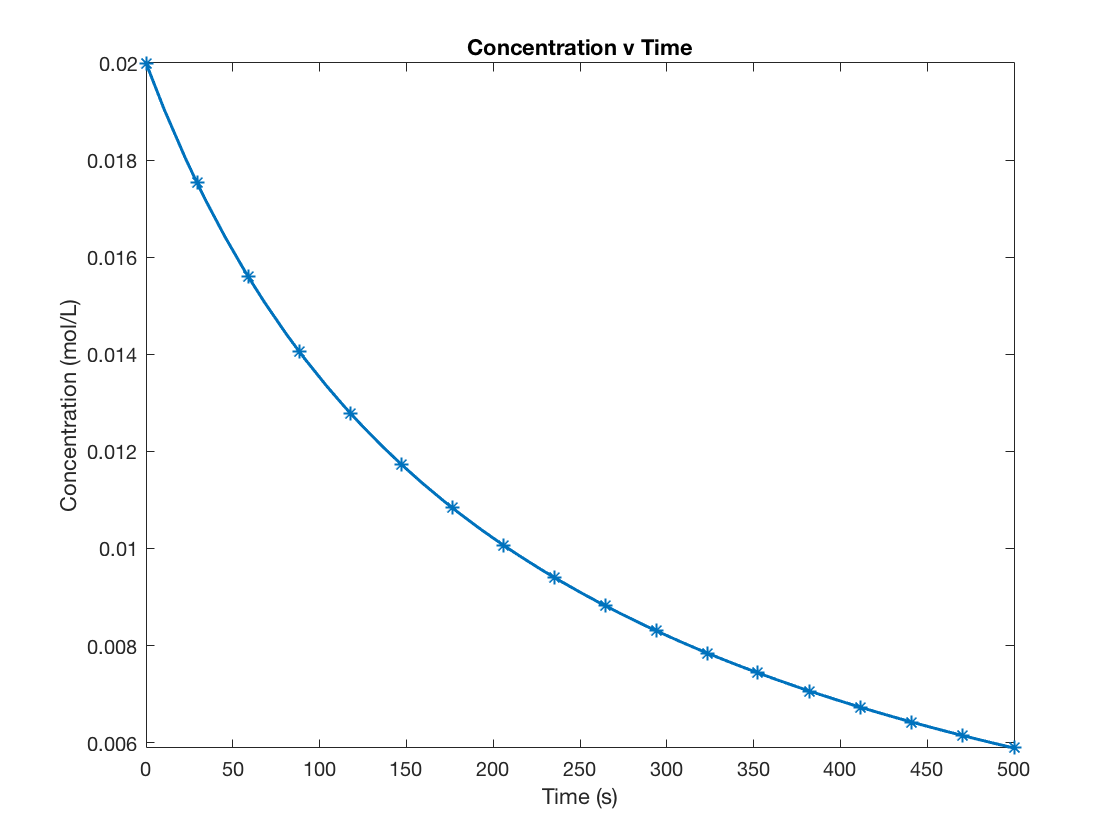


initialConcentration = 0.02;
rateConstant = 0.2396;
A = subs(A, {A0, k}, {initialConcentration, rateConstant});
timeSpan = [0 500];
f1 = fplot(@(t) A(t), timeSpan, 'Marker', '*');
f1.LineWidth = 1.5;
hold on;
xlabel('Time (s)');
ylabel('Concentration (mol/L)');
title('Concentration v Time')